# Linear Control Design II - Group Work Problem Module 10

## Description

The suspension system is a key component of a vehicle directly affecting the passenger comfort and the ability of the vehicle itself to hold the road. In active suspension system an actuator is positioned between the sprung mass of the vehicle and the unsprung mass (wheel, tyre, brake, etc.) parallel to the suspension elements with the objective of pulling/pushing the vehicle body in order to suppress the vibrations due to road irregularities.

### Quarter-car suspension system

A simplified car suspension system is shown on the following figure

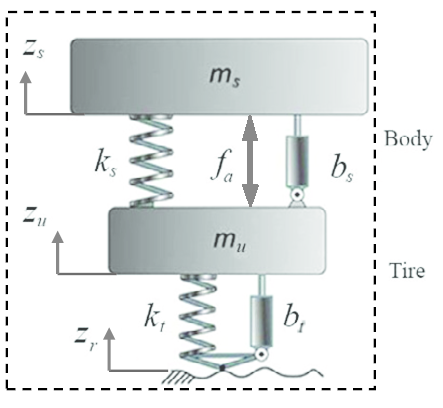

where

- $m_s, \, b_s, \, k_s$ are the mass, damping and stiffness of the sprung element (quarter-car)

- $m_u, \, b_t, \, k_t$ are the mass, damping and stiffness of the unsprung element (wheel-tyre-brake)

- $z_s$ is the displacement of the sprung element

- $z_u$ is the displacement of the unsprung element

- $z_r$ is the displacement of the road

- $f_a$ is the force exerted by an hydraulic actuator placed between the sprung and unsprung elements

The applied force on the tyre from the road 

$f_d =  b_t\dot{z}_r + k_tz_r$                                                               (1)

is considered as an unknown disturbance in the sytem, which should be properly handled by the active suspension.

The numerical values for the model parameters are provided right below.

% Model paramters (RG)
SIM_TIME = 100;
STEP_SIZE = 0.01;
% System parameters
m_s = 243; % sprung mass [kg]
m_u = 40; % unsprung mass [kg]
b_s = 370; % damping coefficient [N*s/m]
b_t = 414; % tyre damping coefficient [N*s/m]
k_s = 14761; % stiffness coefficient [N/m]
k_t = 124660; % tyre stiffness coefficient [N/m]

### Open-loop system analysis

**Problem 1** Looking at the diagram of the quarter-car suspension and applying Newton's second law derive a state space model of the system. Identify state variables, control inputs and possible disturbances. Then compute the stationary state when the control input and the disturbnace are equal to zero.  


$$m_s \cdot \ddot{z}_s=f_a-b_s(\dot{z}_s-\dot{z}_u)-k_s(z_s-z_u) \\
m_u \cdot \ddot{z}_u=b_s(\dot{z}_s-\dot{z}_u)-b_t\dot{z}_u+k_s(z_s-z_u)-k_tz_u+f_d-f_a$$



$$x=[z_s \ \dot{z}_s \ z_u \ \dot{z}_u]^T\\
u=f_a\\
v=f_d$$


% Your solutions goes here
A = [0           1      0       0;
    -k_s/m_s -b_s/m_s k_s/m_s b_s/m_s;
    0            0      0       1;
    k_s/m_u  b_s/m_u -(k_s+k_t)/m_u -(b_s+b_t)/m_u]

A = 	1.0e+03 *

         0    0.0010         0         0
   -0.0607   -0.0015    0.0607    0.0015
         0         0         0    0.0010
    0.3690    0.0092   -3.4855   -0.0196


B = [0;1/m_s;0;-1/m_u]

B =          0
    0.0041
         0
   -0.0250


Bv = [0;0;0;1/m_u]

Bv =          0
         0
         0
    0.0250


x0 = [0.01;0;0.01;0];
u0 = [0;0;0];

**Problem 2** Draw a block diagram of the system and then implement the model in Simulink.

% Your solution goes here
[xss,uss,yss] = trim('MyActiveSusp',x0,u0,[],[],[1;2;3],[])

xss = 	1.0e+-11 *

    0.2066
    0.0000
    0.2066
   -0.0000


uss =      0
     0
     0


yss = 	1.0e+-11 *

    0.2066
    0.0000
    0.2066
   -0.0000
   -0.0000


[xss,uss,yss] = trim('QuarterCar_ActiveSusp_Simulink2019b',x0,u0,[],[],[1;2;3],[])

xss = 	1.0e+-13 *

   -0.5939
   -0.0393
   -0.5939
   -0.0393


uss = 	1.0e+-32 *

   -0.0433
    0.0241
    0.3484


yss = 	1.0e+-13 *

   -0.5939
   -0.0393
   -0.5939
   -0.0393
    0.0015


**Problem 3 **Set the initial position of the sprung element to $z_s = -0.05\mathrm{m}$ and simulate the response of the system when all inputs are at zero and the other state variables retain the stationary value.

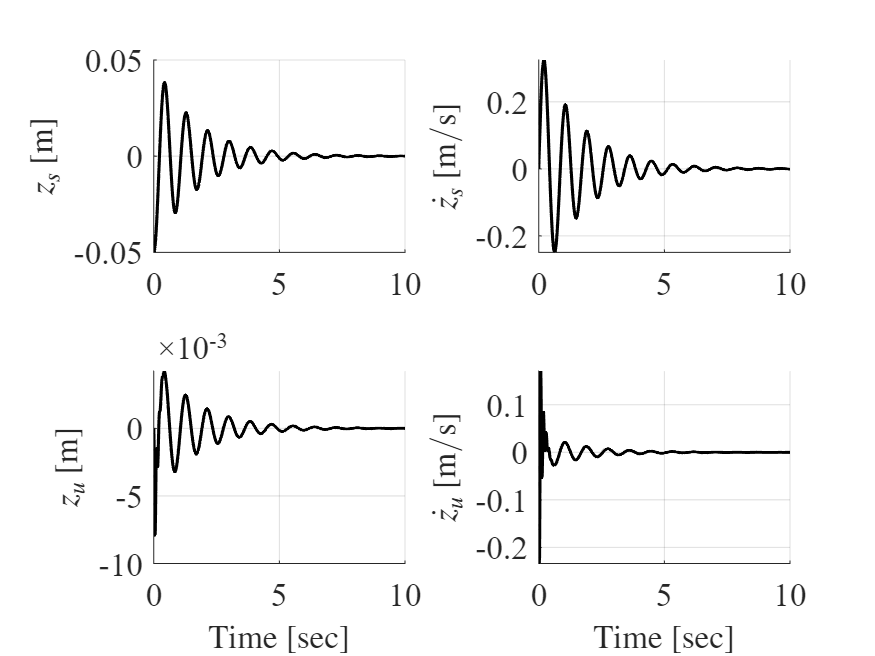

% Your solutions goes here

SIM_TIME = 10;
x0 = [-0.05;0;0;0];
sim('MyActiveSusp.slx',SIM_TIME,[],[]);
time_det = logsout.getElement('zs').Values.Time;
z_s = logsout.getElement('zs').Values.Data;
z_s_dot = logsout.getElement('zs_dot').Values.Data;
z_u = logsout.getElement('zu').Values.Data;
z_u_dot = logsout.getElement('zu_dot').Values.Data;

% sim('QuarterCar_ActiveSusp_Simulink2019b.slx',SIM_TIME,[],[]);
% time_det = logsout.getElement('z_s').Values.Time;
% z_s = logsout.getElement('z_s').Values.Data;
% z_s_dot = logsout.getElement('z_s_dot').Values.Data;
% z_u = logsout.getElement('z_u').Values.Data;
% z_u_dot = logsout.getElement('zu_dot').Values.Data;


figure, h1 = subplot(2,2,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s,'k','LineWidth',1.5)
ylabel('$z_s$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,2,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_s_dot,'k','LineWidth',1.5)
ylabel('$\dot{z}_s$ [m$/$s]','FontName','times','FontSize',16,'Interpreter','latex')
h3 = subplot(2,2,3); set(h3,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_u,'k','LineWidth',1.5)
ylabel('$z_u$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
h4 = subplot(2,2,4); set(h4,'FontName','times','FontSize',16)
hold on, grid on
plot(time_det,z_u_dot,'k','LineWidth',1.5)
ylabel('$\dot{z}_u$ [m$/$s]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

**Problem 4 **Assess the open-loop characteristics of the

- vertical acceleration $\ddot{z}_s$

- tire deflection $(z_u-z_r)$

- suspension deflection $(z_s-z_u)$

in terms of largest deviation from the stationary state, decay rate and settling time when the system is subject to the deterministic road profile $(z_r(t),\dot{z}_r(t))_\mathrm{det}$.

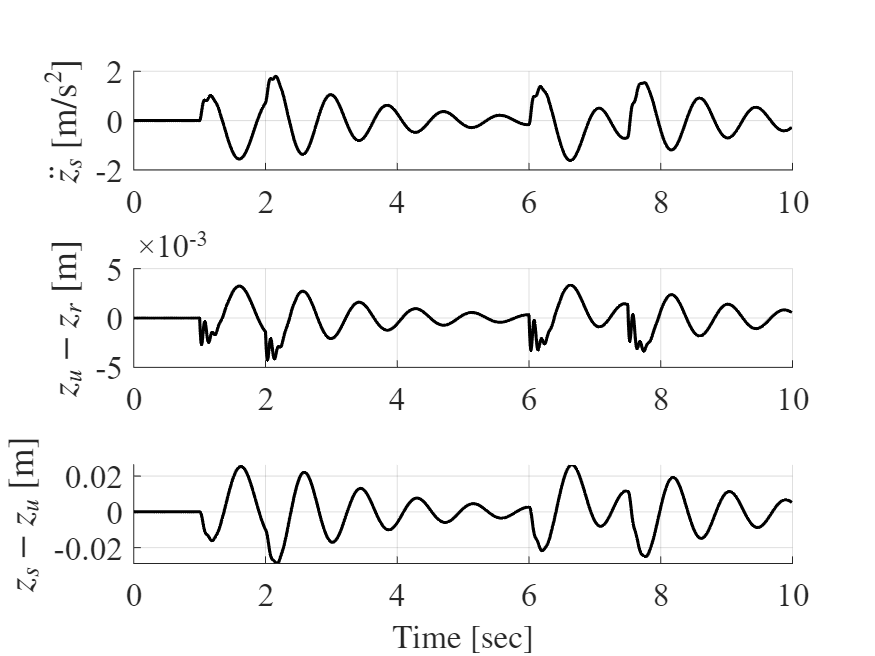

% Your solutions goes here

% Road profiles for open simulations (RG)
load road_profile.mat
time_det = time_det'; % column vector
z_r_det = z_r_det'; % column vector
% [t_det,z_r_det,z_r_dot_det] - deterministic road profile where t_det is the
% travelling time, z_r_det is the vertical road displacement and z_r_dot_det
% is the rate of change of the road profile.
% The profile has been generated for a car traveling with a forward
% speed of 40 km/h

SIM_TIME = time_det(end);
x0 = zeros(4,1);
f_a = zeros(length(time_det),1);
sim('MyActiveSusp.slx',SIM_TIME,[],[time_det f_a z_r_det z_r_dot_det])


z_s = logsout.getElement('zs').Values.Data;
z_s_dot = logsout.getElement('zs_dot').Values.Data;
z_s_ddot = logsout.getElement('zs_dot_dot').Values.Data;
z_u = logsout.getElement('zu').Values.Data;
z_u_dot = logsout.getElement('zu_dot').Values.Data;

% tire deflection
tire_defl = z_u - z_r_det;
% suspension deflection
susp_defl = z_s - z_u;

figure
h6 = subplot(3,1,1);
set(h6,'FontName','tiems','Fontsize',16)
hold on
grid on
plot(time_det,z_s_ddot,'k','LineWidth',1.5);
ylabel('$\ddot{z}_s$ [m/s$^2$]','Interpreter','latex')

h7 = subplot(3,1,2);
set(h7,'FontName','tiems','Fontsize',16)
hold on
grid on
plot(time_det,tire_defl,'k','LineWidth',1.5);
ylabel('$z_u-z_r$ [m]','Interpreter','latex')

h8 = subplot(3,1,3);
set(h8,'FontName','tiems','Fontsize',16)
hold on
grid on
plot(time_det,susp_defl,'k','LineWidth',1.5);
ylabel('$z_s-z_u$ [m]','Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

max_z_s_ddot = max(abs(z_s_ddot))

max_z_s_ddot = 1.7917

dsp1=['The max peak of the vertical acceleration in open loop is ',num2str(max_z_s_ddot),' [m/s^2]'];
disp(dsp1)

The max peak of the vertical acceleration in open loop is 1.7917 [m/s^2]


max_tire_defl = max(abs(tire_defl));
disp2 = ['The maxium peak of the tire deflection in open loop is ',num2str(max_tire_defl),' [m]'];
disp(disp2)

The maxium peak of the tire deflection in open loop is 0.0042823 [m]


max_susp_defl = max(abs(susp_defl));
disp3 = ['The maxium peak of the suspension deflection in open loop is ',num2str(max_susp_defl),' [m]'];
disp(disp3)

The maxium peak of the suspension deflection in open loop is 0.028907 [m]


% natural frequency and damping ratio
[wn,zeta] = damp(A)

wn =    59.0183
   59.0183
    7.3723
    7.3723


zeta =     0.1685
    0.1685
    0.0836
    0.0836


T_osc = 2*pi./[wn(1) wn(3)]

T_osc =     0.1065    0.8523


% Decay rate
alpha = -wn(3)*zeta(3)

alpha = -0.6162

% Settling time
t_set = 5/abs(alpha)

t_set = 8.1137

**Problem 5 **Compute the eigenvalues of the system and asses the internal stability properties. Calculate the damping rato and natural frequency of each couple of complex poles.

% Your solutions goes here
lambda_A_ol = eig(A);
disp(lambda_A_ol)

  -9.9451 +58.1744i
  -9.9451 -58.1744i
  -0.6162 + 7.3465i
  -0.6162 - 7.3465i



wn_A_ol = sqrt(real(lambda_A_ol).^2+imag(lambda_A_ol).^2)

wn_A_ol =    59.0183
   59.0183
    7.3723
    7.3723


zeta_A_ol = -real(lambda_A_ol)/wn_A_ol

zeta_A_ol =     0.1685         0         0         0
    0.1685         0         0         0
    0.0104         0         0         0
    0.0104         0         0         0


**Problem 6** Calculate the transfer function from the control input $f_a$ to the vertical acceleration of sprung mass $\ddot{z}_s$. Determine the position of the system poles and conclude about extenal stability.


$$\ddot{z}_s = -\frac{k_s}{m_s}z_s-\frac{b_s}{m_s}\dot{z}_s+\frac{k_s}{m_s}z_u+\frac{b_s}{m_s}\dot{z}_u$$



$$C = \left[-\frac{k_s}{m_s} \ -\frac{b_s}{m_s} \ \frac{k_s}{m_s} \ \frac{b_s}{m_s}\right]$$


% Your solutions goes here
C = [-k_s/m_s -b_s/m_s k_s/m_s b_s/m_s];
[numG,denG] = ss2tf(A,[B,Bv],C,zeros(1,2),1);
G = tf(numG,denG)

G =
 
    -0.04433 s^3 - 1.833 s^2 - 22.12 s - 779.1
  ----------------------------------------------
  s^4 + 21.12 s^3 + 3562 s^2 + 5374 s + 1.893e05
 
Continuous-time transfer function.



**Problem 7** Select a suitable sampling time $T_s$ and discretize the continuous time model obtained in Problem 1.

Sample frequency should be at least 10 times faster than the largest natural frequency. It means, the smallest period of oscilation of the system will be taken into consideration.

% Your solutions goes here
min_T_oc = min(T_osc);
Ts = min_T_oc/10;
disp(Ts)

    0.0106



[F,G] = c2d(A,B,Ts);
[~,Gv] = c2d(A,Bv,Ts);

susp_ss_dt = ss(F,[G Gv],C,zeros(1,2),Ts)

susp_ss_dt =
 
  A = 
              x1         x2         x3         x4
   x1     0.9967    0.01055   0.002325  8.887e-05
   x2    -0.6081     0.9814     0.3312    0.01665
   x3    0.01879  0.0005399     0.8215   0.008992
   x4      3.285     0.1011     -31.31     0.6461
 
  B = 
               u1          u2
   x1    2.24e-07   7.868e-09
   x2    4.12e-05   2.222e-06
   x3  -1.273e-06   1.281e-06
   x4  -0.0002226   0.0002248
 
  C = 
           x1      x2      x3      x4
   y1  -60.74  -1.523   60.74   1.523
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.010646 seconds
Discrete-time state-space model.

